## ***Q-1***

real = [1,2,3; 4,5,6; 7,8,0]; % Define the real part of the matrix
imag = [9,8,7; 6,5,4; 3,2,1]; % Define the imaginary part of the matrix
B = complex(real,imag) % Combine the real and imaginary parts to form a complex matrix

B =    1.0000 + 9.0000i   2.0000 + 8.0000i   3.0000 + 7.0000i
   4.0000 + 6.0000i   5.0000 + 5.0000i   6.0000 + 4.0000i
   7.0000 + 3.0000i   8.0000 + 2.0000i   0.0000 + 1.0000i


## ***Q-2***

A = [1,2,3; 4,5,6; 7,8,0] % Define matrix A

A =      1     2     3
     4     5     6
     7     8     0


B1 = A([1,3],:) % Extract the 1st and 3rd rows of A

B1 =      1     2     3
     7     8     0


B2 = A(:,[1,1,1]); % Repeat the 1st column of A three times
B2 = B2(end:-1:1,:) % Reverse the order of rows in B2

B2 =      7     7     7
     4     4     4
     1     1     1


B3 = A(:,end:-1:1) % Reverse the order of columns in A

B3 =      3     2     1
     6     5     4
     0     8     7


## ***Q-3***

A = zeros(3,8) % Create a 3x8 matrix filled with zeros

A =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


I = eye(3,8) % Create a 3x8 extended identity matrix

I =      1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0


## ***Q-4***

a = 6.172; 
b = 10.8752;
T = 1:2:50 % Define the temperature range

T =      1     3     5     7     9    11    13    15    17    19    21    23    25    27    29    31    33    35    37    39    41    43    45    47    49


p = power(10, b + ((0.09245 .*a ./ T))) % Calculate the vapor pressure

p = 1.0e+11 *

    2.7913    1.1625    0.9757    0.9051    0.8682    0.8454    0.8300    0.8189    0.8105    0.8040    0.7987    0.7943    0.7907    0.7877    0.7850    0.7827    0.7807    0.7789    0.7774    0.7759    0.7747    0.7735    0.7725    0.7715    0.7706


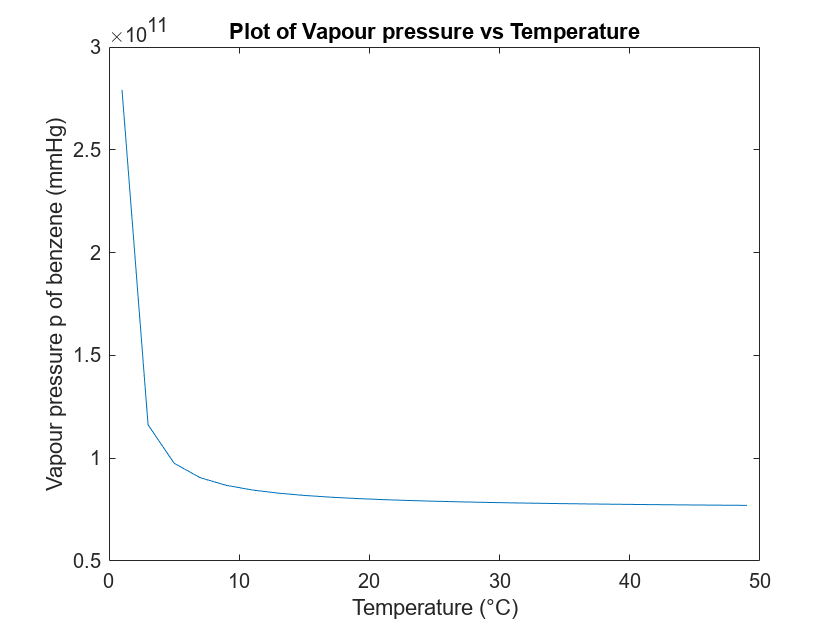


figure;  % Create a new figure
plot(T,p) % Plot P vs T
xlabel('Temperature (°C)');
ylabel('Vapour pressure p of benzene (mmHg)');
title('Plot of Vapour pressure vs Temperature');

## ***Q-5***

a = 5; 
b = 2;
y = 8;
x = 0:0.1:10  % Define the x range  

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


Z = exp(-a*cos(x)) + 10*sqrt(y)*cos(b*x) % Calculate Z

Z =    28.2910   27.7274   26.0590   23.3524   19.7158   15.2945   10.2652    4.8292   -0.7952   -6.3816  -11.7033  -16.5418  -20.6933  -23.9740  -26.2226  -27.2991  -27.0788  -25.4407  -22.2498  -17.3368  -10.4775   -1.3854   10.2706   24.8048   42.3985   62.9344   85.8138  109.8206  133.1120  153.4001  168.3274  175.9592  175.2447  166.2838  150.3019  129.3400  105.7767   81.8466   59.2940   39.2261   22.1491    8.1171   -3.0842  -11.7785  -18.2921  -22.9016  -25.8207  -27.2117  -27.2055  -25.9229


sinz = sin(Z) % Calculate sin(Z)

sinz =    -0.0167    0.5201    0.7994   -0.9781    0.7619    0.4018   -0.7449   -0.9932   -0.7140   -0.0982    0.7598    0.7405   -0.9630    0.9163   -0.8866   -0.8278   -0.9304   -0.3031    0.2558    0.9983    0.8688   -0.9829   -0.7485   -0.3221   -0.9999    0.1024   -0.8365    0.1348    0.9188    0.5124   -0.9684    0.0300   -0.6323    0.2188   -0.4746   -0.5096   -0.8611    0.1644    0.3860    0.9990   -0.1573    0.9656   -0.0573    0.7089    0.5290    0.7898   -0.6350   -0.8736   -0.8766   -0.7105


sum_of_squared_diff = (norm(Z-sinz).^2) % Calculate the sum of squared differences between Z and sin(Z)

sum_of_squared_diff = 5.1557e+05

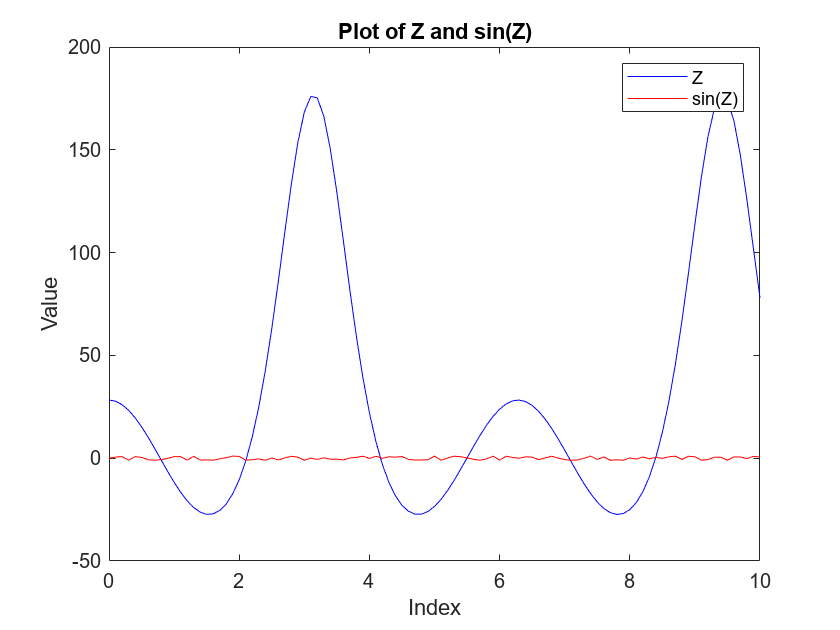


figure; % Create a new figure
plot(x, Z, 'b') % Plot the original function Z and sin(Z) on the same graph
hold on;
plot(x, sinz, 'r')

xlabel('Index');
ylabel('Value');
title('Plot of Z and sin(Z)');
legend('Z', 'sin(Z)');

## Q-6

shape_param = 1;
scale_param = 2;
threshold_param = -2; % Set the parameters

pd = makedist('GeneralizedPareto', 'k', shape_param, 'sigma', scale_param,'theta', threshold_param); % Create a Generalized Pareto Distribution object
n = random(pd,[1 10])  % Generate 10 random numbers from the distribution

n =     3.7500    0.8933   -0.6381    3.6274   -0.6824   -1.1879    5.0193   13.0332    2.7414    2.2740


## Q-7

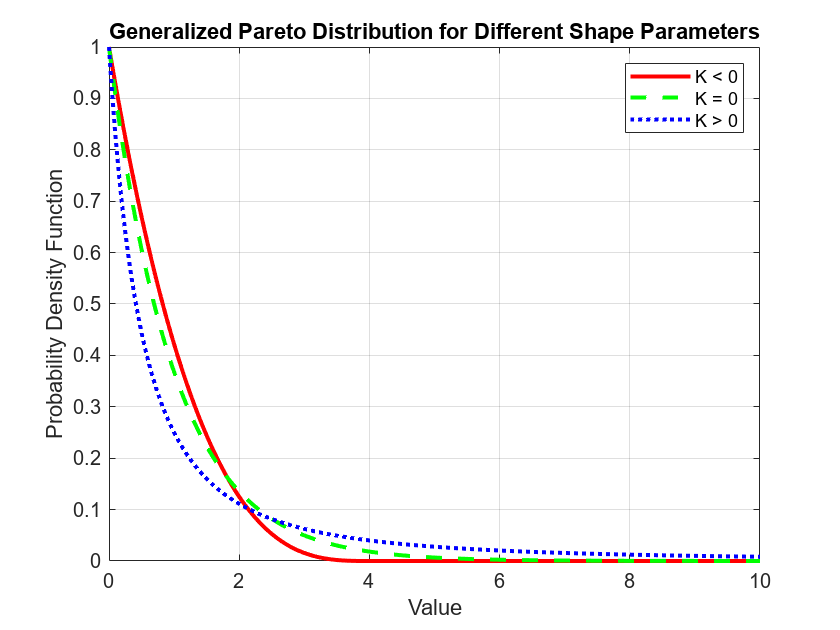

x = linspace(0,10,1000); % Define the x range
y1 = gppdf(x,-.25,1,0); % Calculate the PDF for K < 0
y2 = gppdf(x,0,1,0); % Calculate the PDF for K = 0
y3 = gppdf(x,1,1,0); % Calculate the PDF for K > 0

figure; % Create a new figure
plot(x,y1,'r-', 'LineWidth', 2) % Plot the PDF for K < 0 in red solid line
hold on; % Hold the current plot
plot(x,y2,'g--', 'LineWidth', 2) % Plot the PDF for K = 0 in green dashed line
plot(x,y3,'b:', 'LineWidth', 2) % Plot the PDF for K > 0 in blue dotted line

xlabel('Value'); % Label the x-axis
ylabel('Probability Density Function'); % Label the y-axis
title('Generalized Pareto Distribution for Different Shape Parameters'); % Add a title to the plot
legend({'K < 0' 'K = 0' 'K > 0'}, 'Location', 'northeast'); % Add a legend to the plot
grid on; % Add a grid to the plot